Signal generation

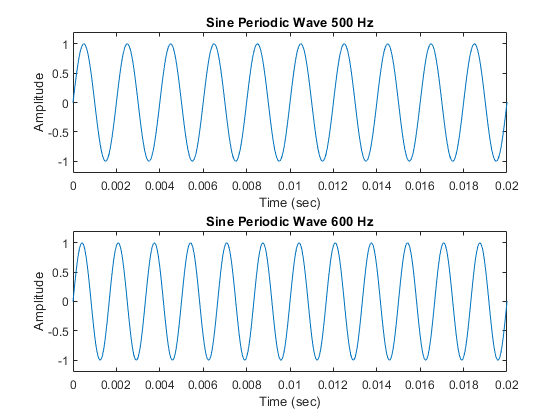

fs = 20000;
t = 0:1/fs:1.5;

x1 = sin(2*pi*500*t); 
x2 = sin(2*pi*600*t);

subplot(2,1,1);
plot(t,x1);
axis([0 0.02 -1.2 1.2]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('Sine Periodic Wave 500 Hz');
subplot(2,1,2);
plot(t,x2);
axis([0 0.02 -1.2 1.2]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('Sine Periodic Wave 600 Hz'); 

Calculate doppler

L = length(t);      % Signal length
P = abs(x1fft/L);
P1 = P(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);

x1fft = fft(x1);
x2fft = fft(x2);

plot(x1fft,P1);

Error using plot
Vectors must be the same length.